Manuscript ID: RSFS-2023-0064.R2 - Analysis of micropolar elastic multilaminated composite and its application to bio-ceramic materials for bone reconstruction.

Journal: Interface Focus 

Autores: R. Rodríguez-Ramos, Y. Espinosa-Almeyda, D. Guinovart-Sanjuán, H. Camacho-Montes, P. Rodríguez-Bermúdez, H. Brito-Santana, J. A. Otero, and F. J. Sabina.

Corresponding author email: yoanh.espinosa@uacj.mx

This program reproduces Figures 4 and 5 of Section 4.3: Application of the micropolar theory for bone reconstruction.

The materials for the computations are given in Table 5 within the manuscript.

 The properties of Material A were taken from Table 1 of  

  

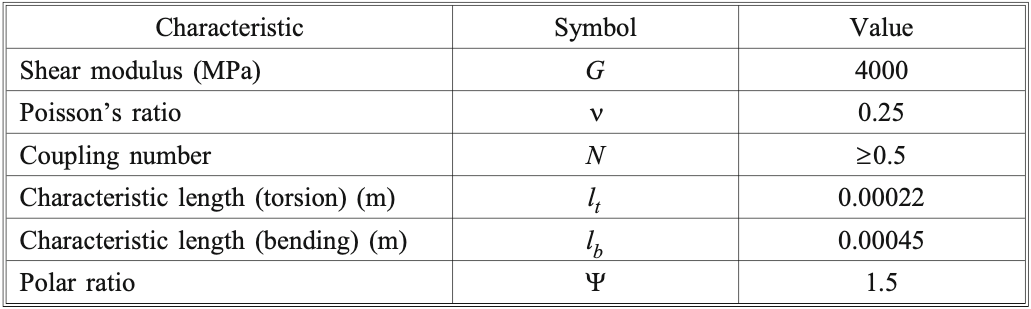  

clear
G=4e9;nu=0.25;N=0.6;
lt=0.00022;lb=0.00045;Phi=1.5;

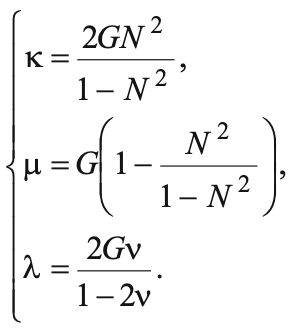

kappa = 2*G*N^2/(1-N^2);
mu = G*(1-N^2/(1-N^2));
lambda = 2*G*nu/(1-2*nu);

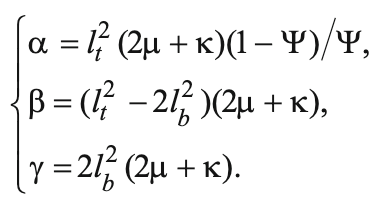

alpha=lt^2*(2*mu+kappa)*(1-Phi)/Phi;
beta=(lt^2-2*lb^2)*(2*mu+kappa);
gamma=2*lb^2*(2*mu+kappa);
C_1122 = lambda;
C_1212 = mu+kappa;
C_1221 = mu;
for i=1:3
    for j=1:3
        for k=1:3
            for l=1:3
              CA(i,j,k,l)=C_1122*kroneckerDelta(sym(i),sym(j))*kroneckerDelta(sym(k),sym(l))+...
                         C_1212*kroneckerDelta(sym(i),sym(k))*kroneckerDelta(sym(j),sym(l))+...
                         C_1221*kroneckerDelta(sym(i),sym(l))*kroneckerDelta(sym(j),sym(k));
             end
        end
    end
end
CA9=double(TransAB(CA));
D_1122 = alpha;
D_1212 = gamma;
D_1221 = beta;
for i=1:3
    for j=1:3
        for k=1:3
            for l=1:3
              DA(i,j,k,l)=D_1122*kroneckerDelta(sym(i),sym(j))*kroneckerDelta(sym(k),sym(l))+...
                          D_1212*kroneckerDelta(sym(i),sym(k))*kroneckerDelta(sym(j),sym(l))+...
                          D_1221*kroneckerDelta(sym(i),sym(l))*kroneckerDelta(sym(j),sym(k));
             end
        end
    end
end
DA9=double(TransAB(DA));

The properties of Material B were taken from Tabla 3 of Yang and Lakes

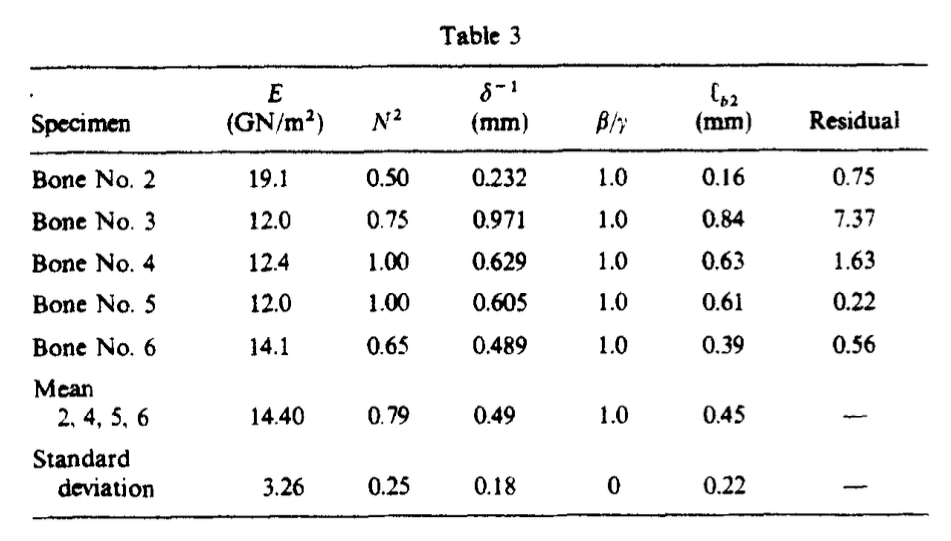

nu = 0.3;
E = 14.4e9;G=E/2/(1+nu);
N = 0.7;
lb=0.00045;Phi=1.5;lt=2*lb;
kappa = 2*G*N^2/(1-N^2);
mu = G*(1-N^2/(1-N^2));
lambda = 2*G*nu/(1-2*nu);

gamma=2*lb^2*(2*mu+kappa);
beta=gamma;
alpha=lt^2*(2*mu+kappa)*(1-Phi)/Phi;
C_1122 = lambda;
C_1212 = mu+kappa;
C_1221 = mu;
for i=1:3
    for j=1:3
        for k=1:3
            for l=1:3
              CB(i,j,k,l)=C_1122*kroneckerDelta(sym(i),sym(j))*kroneckerDelta(sym(k),sym(l))+...
                         C_1212*kroneckerDelta(sym(i),sym(k))*kroneckerDelta(sym(j),sym(l))+...
                         C_1221*kroneckerDelta(sym(i),sym(l))*kroneckerDelta(sym(j),sym(k));
             end
        end
    end
end
CB9=double(TransAB(CB));
D_1122 = alpha;
D_1212 = gamma;
D_1221 = beta;
for i=1:3
    for j=1:3
        for k=1:3
            for l=1:3
              DB(i,j,k,l)=D_1122*kroneckerDelta(sym(i),sym(j))*kroneckerDelta(sym(k),sym(l))+...
                          D_1212*kroneckerDelta(sym(i),sym(k))*kroneckerDelta(sym(j),sym(l))+...
                          D_1221*kroneckerDelta(sym(i),sym(l))*kroneckerDelta(sym(j),sym(k));
             end
        end
    end
end
DB9=double(TransAB(DB));

c=zeros(9,9);
CA=CA9;CB=CB9;

FVA=linspace(0,1,100);
for i=1:100
c(1,1) = P(CA(1,1),CB(1,1),FVA(i))-P(CA(1,3)^2*CA(3,3)^(-1),CB(1,3)^2*CB(3,3)^(-1),FVA(i))+...
      (P(CA(1,3)*CA(3,3)^(-1),CB(1,3)*CB(3,3)^(-1),FVA(i)))^2/(P(CA(3,3)^(-1),CB(3,3)^(-1),FVA(i)));
c(2,2) = c(1,1);
c(3,3) = (P(CA(3,3)^(-1),CB(3,3)^(-1),FVA(i)))^(-1);
c(1,2) = P(CA(1,2),CB(1,2),FVA(i))-P(CA(1,3)^2*CA(3,3)^(-1),CB(1,3)^2*CB(3,3)^(-1),FVA(i))+...
      (P(CA(1,3)*CA(3,3)^(-1),CB(1,3)*CB(3,3)^(-1),FVA(i)))^2/(P(CA(3,3)^(-1),CB(3,3)^(-1),FVA(i)));
c(1,3) = (P(CA(1,3)*CA(3,3)^(-1),CB(1,3)*CB(3,3)^(-1),FVA(i)))/(P(CA(3,3)^(-1),CB(3,3)^(-1),FVA(i)));
c(2,3) = c(1,3);
c(4,4) = (P(CA(4,4)^(-1),CB(4,4)^(-1),FVA(i)))^(-1);
c(5,5) = c(4,4);
c(6,6) = P(CA(6,6),CB(6,6),FVA(i));
c(7,7) = P(CA(7,7),CB(7,7),FVA(i))-P(CA(7,4)^2*CA(4,4)^(-1),CB(7,4)^2*CB(4,4)^(-1),FVA(i))+...
      (P(CA(7,4)*CA(4,4)^(-1),CB(7,4)*CB(4,4)^(-1),FVA(i)))^2/(P(CA(4,4)^(-1),CB(4,4)^(-1),FVA(i)));
c(8,8) = P(CA(8,8),CB(8,8),FVA(i))-P(CA(8,5)^2*CA(5,5)^(-1),CB(8,5)^2*CB(5,5)^(-1),FVA(i))+...
      (P(CA(8,5)*CA(5,5)^(-1),CB(8,5)*CB(5,5)^(-1),FVA(i)))^2/(P(CA(5,5)^(-1),CB(5,5)^(-1),FVA(i)));
c(4,7) = (P(CA(4,7)*CA(4,4)^(-1),CB(4,7)*CB(4,4)^(-1),FVA(i)))/(P(CA(4,4)^(-1),CB(4,4)^(-1),FVA(i)));
c(5,8) = (P(CA(5,8)*CA(5,5)^(-1),CB(5,8)*CB(5,5)^(-1),FVA(i)))/(P(CA(5,5)^(-1),CB(5,5)^(-1),FVA(i)));
c(6,9) = P(CA(6,9),CB(6,9),FVA(i));
c(9,9) = P(CA(9,9),CB(9,9),FVA(i));
c(1,6) = P(CA(1,6),CB(1,6),FVA(i));
c(2,6) = P(CA(2,6),CB(2,6),FVA(i));
c(1,9) = P(CA(1,9),CB(1,9),FVA(i));
c(2,9) = P(CA(2,9),CB(2,9),FVA(i));
if i==50
    disp(FVA(i))
    disp(c)
end
c11(i)=c(1,1)/1e9;c12(i)=c(1,2)/1e9;c13(i)=c(1,3)/1e9;c33(i)=c(3,3)/1e9;c44(i)=c(4,4)/1e9;c66(i)=c(6,6)/1e9;
c77(i)=c(7,7)/1e9;c69(i)=c(6,9)/1e9;c47(i)=c(4,7)/1e9;
end

    0.4949



   1.0e+10 *

    1.5433    0.5879    0.5668         0         0         0         0         0         0
         0    1.5433    0.5668         0         0         0         0         0         0
         0         0    1.4859         0         0         0         0         0         0
         0         0         0    0.7956         0         0    0.1183         0         0
         0         0         0         0    0.7956         0         0    0.1183         0
         0         0         0         0         0    0.8578         0         0    0.0976
         0         0         0         0         0         0    0.8509         0         0
         0         0         0         0         0         0         0    0.8509         0
         0         0         0         0         0         0         0         0    0.8578



d=zeros(9,9);
DA=DA9;DB=DB9;
for i=1:100
d(1,1) = P(DA(1,1),DB(1,1),FVA(i))-P(DA(1,3)^2*DA(3,3)^(-1),DB(1,3)^2*DB(3,3)^(-1),FVA(i))+...
      (P(DA(1,3)*DA(3,3)^(-1),DB(1,3)*DB(3,3)^(-1),FVA(i)))^2/(P(DA(3,3)^(-1),DB(3,3)^(-1),FVA(i)));
d(2,2) = c(1,1);
d(3,3) = (P(DA(3,3)^(-1),DB(3,3)^(-1),FVA(i)))^(-1);
d(1,2) = P(DA(1,2),DB(1,2),FVA(i))-P(DA(1,3)^2*DA(3,3)^(-1),DB(1,3)^2*DB(3,3)^(-1),FVA(i))+...
      (P(DA(1,3)*DA(3,3)^(-1),DB(1,3)*DB(3,3)^(-1),FVA(i)))^2/(P(DA(3,3)^(-1),DB(3,3)^(-1),FVA(i)));
d(1,3) = (P(DA(1,3)*DA(3,3)^(-1),DB(1,3)*DB(3,3)^(-1),FVA(i)))/(P(DA(3,3)^(-1),DB(3,3)^(-1),FVA(i)));
d(2,3) = c(1,3);
d(4,4) = (P(DA(4,4)^(-1),DB(4,4)^(-1),FVA(i)))^(-1);
d(5,5) = c(4,4);
d(6,6) = P(DA(6,6),DB(6,6),FVA(i));
d(7,7) = P(DA(7,7),DB(7,7),FVA(i))-P(DA(7,4)^2*DA(4,4)^(-1),DB(7,4)^2*DB(4,4)^(-1),FVA(i))+...
      (P(DA(7,4)*DA(4,4)^(-1),DB(7,4)*DB(4,4)^(-1),FVA(i)))^2/(P(DA(4,4)^(-1),DB(4,4)^(-1),FVA(i)));
d(8,8) = P(DA(8,8),DB(8,8),FVA(i))-P(DA(8,5)^2*DA(5,5)^(-1),DB(8,5)^2*DB(5,5)^(-1),FVA(i))+...
      (P(DA(8,5)*DA(5,5)^(-1),DB(8,5)*DB(5,5)^(-1),FVA(i)))^2/(P(DA(5,5)^(-1),DB(5,5)^(-1),FVA(i)));
d(4,7) = (P(DA(4,7)*DA(4,4)^(-1),DB(4,7)*DB(4,4)^(-1),FVA(i)))/(P(DA(4,4)^(-1),DB(4,4)^(-1),FVA(i)));
d(5,8) = (P(DA(5,8)*DA(5,5)^(-1),DB(5,8)*DB(5,5)^(-1),FVA(i)))/(P(DA(5,5)^(-1),DB(5,5)^(-1),FVA(i)));
d(6,9) = P(DA(6,9),DB(6,9),FVA(i));
d(9,9) = P(DA(9,9),DB(9,9),FVA(i));
d(1,6) = P(DA(1,6),DB(1,6),FVA(i));
d(2,6) = P(DA(2,6),DB(2,6),FVA(i));
d(1,9) = P(DA(1,9),DB(1,9),FVA(i));
d(2,9) = P(DA(2,9),DB(2,9),FVA(i));
if i==50
    disp(FVA(i))
    disp(d)
end
D11(i)=d(1,1)/1e3;D12(i)=d(1,2)/1e3;D13(i)=d(1,3)/1e3;D33(i)=d(3,3)/1e3;D44(i)=d(4,4)/1e3;D66(i)=d(6,6)/1e3;
D77(i)=d(7,7)/1e3;D69(i)=d(6,9)/1e3;D47(i)=d(4,7)/1e3;
end

    0.4949



   1.0e+10 *

    0.0000   -0.0000   -0.0000         0         0         0         0         0         0
         0    1.2000    0.4000         0         0         0         0         0         0
         0         0    0.0000         0         0         0         0         0         0
         0         0         0    0.0000         0         0    0.0000         0         0
         0         0         0         0    0.6250         0         0    0.0000         0
         0         0         0         0         0    0.0000         0         0    0.0000
         0         0         0         0         0         0    0.0000         0         0
         0         0         0         0         0         0         0    0.0000         0
         0         0         0         0         0         0         0         0    0.0000



f=figure

f =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [403 246 560 420]
       Units: 'pixels'

  Show all properties


f.Position

ans =    403   246   560   420


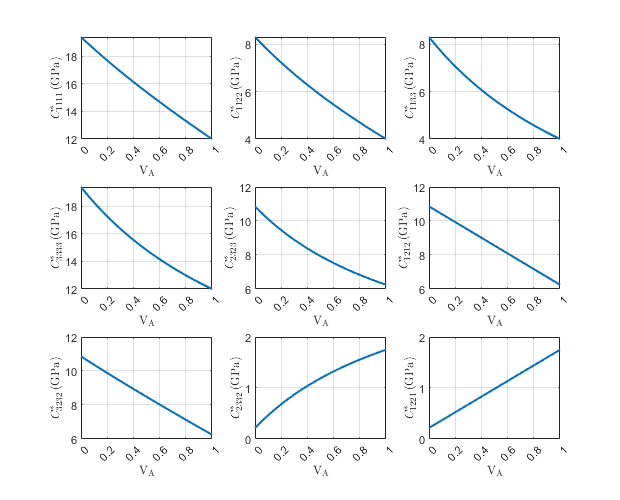

f.Position(3:4) = [620 500];
subplot(3,3,1);plot(FVA,c11,'LineWidth',1.5);grid on;
ylabel('$C_{1111}^{*}\,(\mathrm{GPa})$','FontName','Times New Roman','Interpreter','latex');
xlabel('$\mathrm{V}_\mathrm{A}$','FontName','Times New Roman','Interpreter','latex');
xticks(0:0.2:1)
subplot(3,3,2);plot(FVA,c12,'LineWidth',1.5);grid on;
ylabel('$C_{1122}^{*}\,(\mathrm{GPa})$','FontName','Times New Roman','Interpreter','latex');
xlabel('$\mathrm{V}_\mathrm{A}$','FontName','Times New Roman','Interpreter','latex');
xticks(0:0.2:1)
subplot(3,3,3);plot(FVA,c13,'LineWidth',1.5);grid on;
ylabel('$C_{1133}^{*}\,(\mathrm{GPa})$','FontName','Times New Roman','Interpreter','latex');
xlabel('$\mathrm{V}_\mathrm{A}$','FontName','Times New Roman','Interpreter','latex');
xticks(0:0.2:1)
subplot(3,3,4);plot(FVA,c33,'LineWidth',1.5);grid on;
ylabel('$C_{3333}^{*}\,(\mathrm{GPa})$','FontName','Times New Roman','Interpreter','latex');
xlabel('$\mathrm{V}_\mathrm{A}$','FontName','Times New Roman','Interpreter','latex');
xticks(0:0.2:1)
subplot(3,3,5);plot(FVA,c44,'LineWidth',1.5);grid on;
ylabel('$C_{2323}^{*}\,(\mathrm{GPa})$','FontName','Times New Roman','Interpreter','latex');
xlabel('$\mathrm{V}_\mathrm{A}$','FontName','Times New Roman','Interpreter','latex');
xticks(0:0.2:1)
subplot(3,3,6);plot(FVA,c66,'LineWidth',1.5);grid on;
ylabel('$C_{1212}^{*}\,(\mathrm{GPa})$','FontName','Times New Roman','Interpreter','latex');
xlabel('$\mathrm{V}_\mathrm{A}$','FontName','Times New Roman','Interpreter','latex');
xticks(0:0.2:1)
subplot(3,3,7);plot(FVA,c77,'LineWidth',1.5);grid on;
ylabel('$C_{3232}^{*}\,(\mathrm{GPa})$','FontName','Times New Roman','Interpreter','latex');
xlabel('$\mathrm{V}_\mathrm{A}$','FontName','Times New Roman','Interpreter','latex');
xticks(0:0.2:1)
subplot(3,3,8);plot(FVA,c47,'LineWidth',1.5);grid on;
ylabel('$C_{2332}^{*}\,(\mathrm{GPa})$','FontName','Times New Roman','Interpreter','latex');
xlabel('$\mathrm{V}_\mathrm{A}$','FontName','Times New Roman','Interpreter','latex');
xticks(0:0.2:1)
subplot(3,3,9);plot(FVA,c69,'LineWidth',1.5);grid on;
ylabel('$C_{1221}^{*}\,(\mathrm{GPa})$','FontName','Times New Roman','Interpreter','latex');
xlabel('$\mathrm{V}_\mathrm{A}$','FontName','Times New Roman','Interpreter','latex');
xticks(0:0.2:1)
print('Figure 4','-djpeg','-r600');

g=figure

g =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [403 246 560 420]
       Units: 'pixels'

  Show all properties


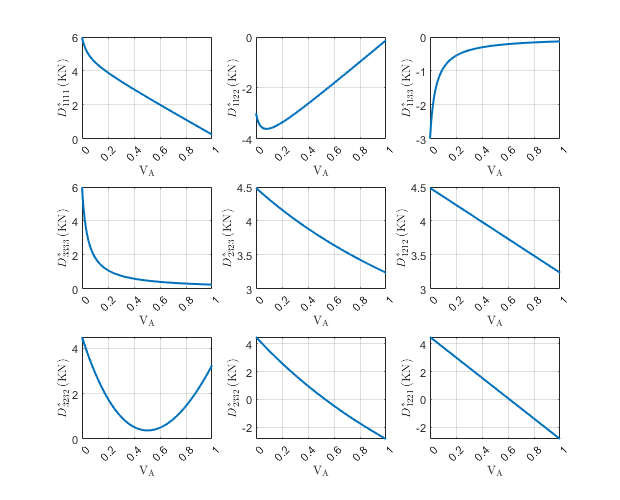

g.Position(3:4) = [620 500];
subplot(3,3,1);plot(FVA,D11,'LineWidth',1.5);grid on;
ylabel('$D_{1111}^{*}\,(\mathrm{KN})$','FontName','Times New Roman','Interpreter','latex');
xlabel('$\mathrm{V}_\mathrm{A}$','FontName','Times New Roman','Interpreter','latex');
xticks(0:0.2:1)
subplot(3,3,2);plot(FVA,D12,'LineWidth',1.5);grid on;
ylabel('$D_{1122}^{*}\,(\mathrm{KN})$','FontName','Times New Roman','Interpreter','latex');
xlabel('$\mathrm{V}_\mathrm{A}$','FontName','Times New Roman','Interpreter','latex');
xticks(0:0.2:1)
subplot(3,3,3);plot(FVA,D13,'LineWidth',1.5);grid on;
ylabel('$D_{1133}^{*}\,(\mathrm{KN})$','FontName','Times New Roman','Interpreter','latex');
xlabel('$\mathrm{V}_\mathrm{A}$','FontName','Times New Roman','Interpreter','latex');
xticks(0:0.2:1)
subplot(3,3,4);plot(FVA,D33,'LineWidth',1.5);grid on;
ylabel('$D_{3333}^{*}\,(\mathrm{KN})$','FontName','Times New Roman','Interpreter','latex');
xlabel('$\mathrm{V}_\mathrm{A}$','FontName','Times New Roman','Interpreter','latex');
xticks(0:0.2:1)
subplot(3,3,5);plot(FVA,D44,'LineWidth',1.5);grid on;
ylabel('$D_{2323}^{*}\,(\mathrm{KN})$','FontName','Times New Roman','Interpreter','latex');
xlabel('$\mathrm{V}_\mathrm{A}$','FontName','Times New Roman','Interpreter','latex');
xticks(0:0.2:1)
subplot(3,3,6);plot(FVA,D66,'LineWidth',1.5);grid on;
ylabel('$D_{1212}^{*}\,(\mathrm{KN})$','FontName','Times New Roman','Interpreter','latex');
xlabel('$\mathrm{V}_\mathrm{A}$','FontName','Times New Roman','Interpreter','latex');
xticks(0:0.2:1)
subplot(3,3,7);plot(FVA,D77,'LineWidth',1.5);grid on;
ylabel('$D_{3232}^{*}\,(\mathrm{KN})$','FontName','Times New Roman','Interpreter','latex');
xlabel('$\mathrm{V}_\mathrm{A}$','FontName','Times New Roman','Interpreter','latex');
xticks(0:0.2:1)
subplot(3,3,8);plot(FVA,D47,'LineWidth',1.5);grid on;
ylabel('$D_{2332}^{*}\,(\mathrm{KN})$','FontName','Times New Roman','Interpreter','latex');
xlabel('$\mathrm{V}_\mathrm{A}$','FontName','Times New Roman','Interpreter','latex');
xticks(0:0.2:1)
subplot(3,3,9);plot(FVA,D69,'LineWidth',1.5);grid on;
ylabel('$D_{1221}^{*}\,(\mathrm{KN})$','FontName','Times New Roman','Interpreter','latex');
xlabel('$\mathrm{V}_\mathrm{A}$','FontName','Times New Roman','Interpreter','latex');
xticks(0:0.2:1)
print('Figure 5','-djpeg','-r600');

#### Function $A_{\textrm{ijkl}} \longrightarrow B_{\textrm{rs}}$

function B=TransAB(A)
    B = sym(zeros(9));
    for i=1:3
        for j=1:3
            if i==j
                r=i;
            elseif (i==2) && (j==3)
                r=4;
            elseif (i==1) && (j==3)
                r=5;  
            elseif (i==1) && (j==2)
                r=6;
            elseif (i==3) && (j==2)
                r=7; 
            elseif (i==3) && (j==1)
                r=8;
            elseif (i==2) && (j==1)
                r=9;
            end
            for k=1:3
                for l=1:3
                    if k==l
                        s=k;
                    elseif (k==2) && (l==3)
                        s=4;
                    elseif (k==1) && (l==3)
                        s=5;  
                    elseif (k==1) && (l==2)
                        s=6;
                    elseif (k==3) && (l==2)
                        s=7; 
                    elseif (k==3) && (l==1)
                        s=8;
                    elseif (k==2) && (l==1)
                        s=9;
                    end
                    B(r,s) = A(i,j,k,l);
                end
            end
        end
    end
end
%%%%%%
function r = P(C_A,C_B,FVA)
            r = C_A.*FVA+C_B.*(1-FVA);
end